syms y(t);
u=exp(-5*t)*cos(2*t+1)+5;
uu=5*diff(u,t,2)+4*diff(u,t)+2*u;
Dy=diff(y,t);
D2y=diff(y,t,2);
D3y=diff(y,t,3);
D4y=diff(y,t,4);
equation=D4y+10*D3y+35*D2y+50*Dy+24*y==uu;
r=dsolve(equation,y(0)==3,Dy(0)==2,D2y(0)==0,D3y(0)==0);
r=collect(collect(r,sin(2*t+1)),cos(2*t+1))

$$model = \frac{M}{{\mathrm{e}}^{-M\,\left(C_{17}+r\,t\right)}+1}$$

$$ans = \frac{664.6}{65.66\,{\mathrm{e}}^{-0.5349\,t}+1.0}$$

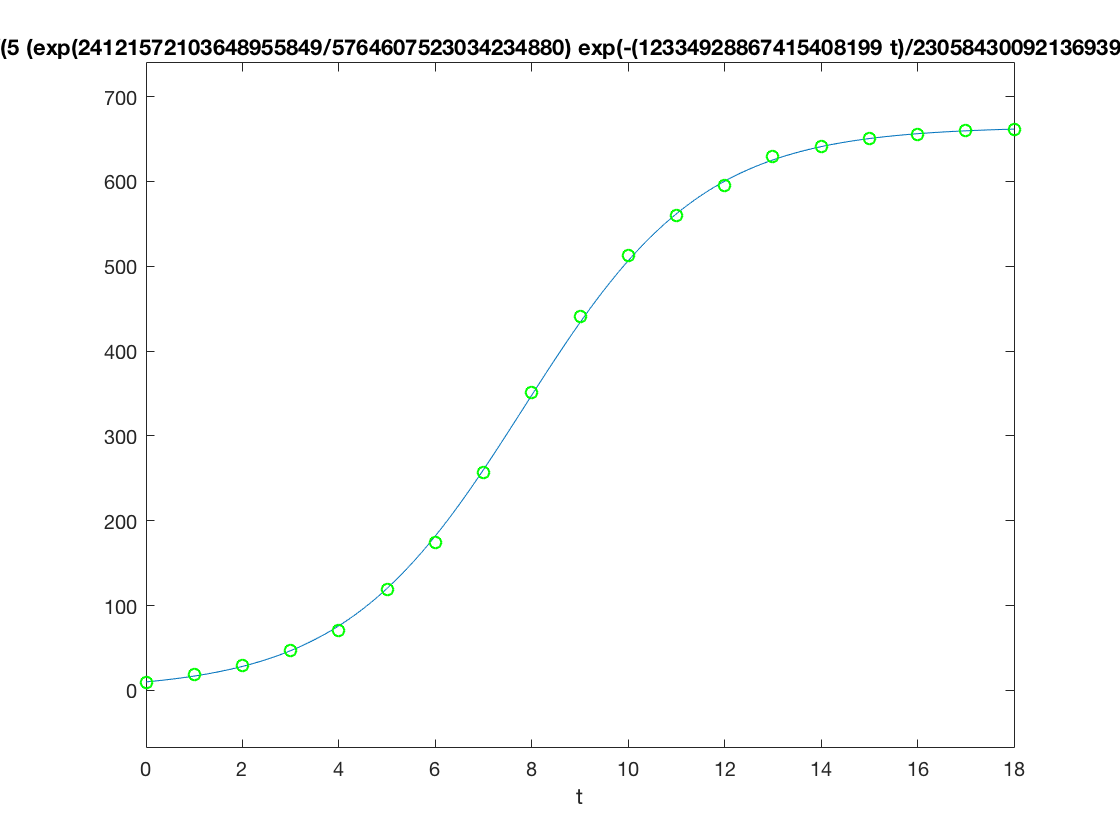

syms t y;
y=dsolve(['D4y+10*D3y+35*D2y+50*Dy+24*y=',...
    '87*exp(-5*t)*cos(2*t+1)+92*exp(-5*t)*sin(2*t+1)+10'])

y=dsolve(['D4y+10*D3y+35*D2y+50*Dy+24*y=',...
    '87*exp(-5*t)*cos(2*t+1)+92*exp(-5*t)*sin(2*t+1)+10'],'y(0)=3',...
    'Dy(0)=2','D2y(0)=0','D3y(0)=0')
simplify(r-y)